# HW 10 - Ch13 - Eigenvalues

## Problem 1

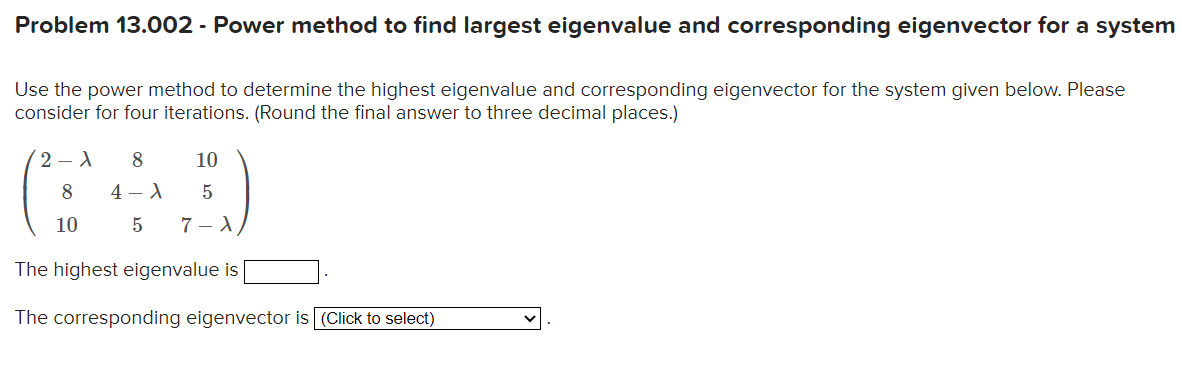

help powereig

  powereig - Computes the dominant eigenvalue and eigenvector using the Power Method
 
  Syntax:
    [eigval, eigvect] = powereig(A, es, maxit)
 
  Inputs:
    A     - Square matrix for which the dominant eigenvalue/vector is sought
    es    - Desired relative error tolerance (stopping criterion, e.g. 0.0001)
    maxit - Maximum number of iterations to perform
 
  Outputs:
    eigval  - Dominant (largest magnitude) eigenvalue of A
    eigvect - Corresponding normalized eigenvector
 
  Example:
    A = [4 1; 2 3];
    [eigval, eigvect] = powereig(A, 0.0001, 100)
 
  Description:
    This function implements the Power Method, an iterative algorithm used 
    to find the largest eigenvalue (in magnitude) and its associated eigenvector.
    The algorithm repeatedly multiplies an arbitrary vector by the matrix A,
    normalizes the result, and estimates convergence based on the change in eigenvalue.



help eig

 eig    Eigenvalues and eigenvectors.
    E = eig(A) produces a column vector E containing the eigenvalues of 
    a square matrix A.
 
    [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    a full matrix V whose columns are the corresponding eigenvectors  
    so that A*V = V*D.
  
    [V,D,W] = eig(A) also produces a full matrix W whose columns are the
    corresponding left eigenvectors so that W'*A = D*W'.
 
    [...] = eig(A,"nobalance") performs the computation with balancing
    disabled, which sometimes gives more accurate results for certain
    problems with unusual scaling. If A is symmetric, eig(A,"nobalance")
    is ignored since A is already balanced.
 
    [...] = eig(A,"balance") is the same as eig(A).
 
    E = eig(A,B) produces a column vector E containing the generalized 
    eigenvalues of square ma


A = [2 8 10; 8 4 5; 10 5 7]; % can leave out lambda
maxit = 4; es = 0.001;
[eigval, eigvect] = powereig(A, es, maxit)

eigval = 19.8895

eigvect =     0.9033
    0.7698
    1.0000


% normalized eigenvector bc the highest one always set to 1

% doublecheck
[V D] = eig(A)

V =    -0.8125   -0.0320    0.5821
    0.3860   -0.7778    0.4960
    0.4369    0.6277    0.6443


D =    -7.1785         0         0
         0    0.2942         0
         0         0   19.8842


Vnorm = V./max(V)

Vnorm =    -1.8596   -0.0510    0.9035
    0.8836   -1.2391    0.7698
    1.0000    1.0000    1.0000


%     yep: largest matches the eigval
%     columns match btwn V and D, V = vector 1st

## Problem 2

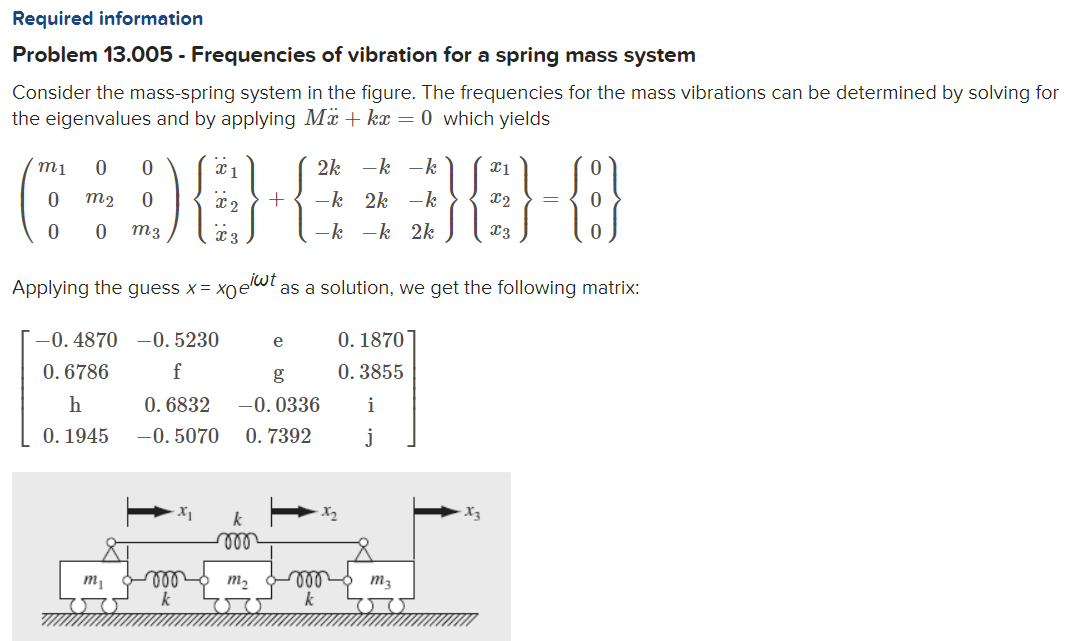

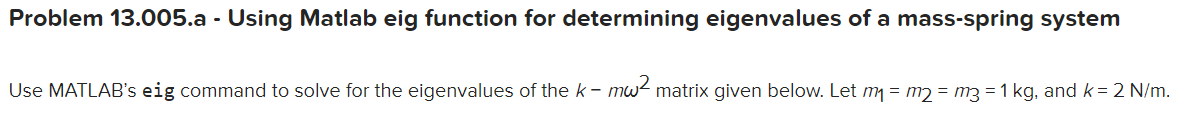

help eig

 eig    Eigenvalues and eigenvectors.
    E = eig(A) produces a column vector E containing the eigenvalues of 
    a square matrix A.
 
    [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    a full matrix V whose columns are the corresponding eigenvectors  
    so that A*V = V*D.
  
    [V,D,W] = eig(A) also produces a full matrix W whose columns are the
    corresponding left eigenvectors so that W'*A = D*W'.
 
    [...] = eig(A,"nobalance") performs the computation with balancing
    disabled, which sometimes gives more accurate results for certain
    problems with unusual scaling. If A is symmetric, eig(A,"nobalance")
    is ignored since A is already balanced.
 
    [...] = eig(A,"balance") is the same as eig(A).
 
    E = eig(A,B) produces a column vector E containing the generalized 
    eigenvalues of square ma


% Spring system setup: FBD, apply F = ma to each
%    Mass 1:
% m*a1 = m*x1_dodot = k*(x2-x1) + k*(x3-x1) mmmmm I don't know: not stretch
%     bc there's the blocks...
%    m*x1_dodot = k*(-2*x1+x2+x3)
% m*x2_dodot = -k*(x2-x1) + k*(x3-x2)
%    m*x2_dodot = k*(-2*x2+x1+x3)
% m*x3_dodot = -k*(x3-x2) - k*(x3-x1)
%    m*x3_dodot = k*(-2*x3+x2+x1)

% m*x_dodot + k*x = 0
%    But pull out the x not the k

% x_dodot = -K/M*x

M = eye(3)*1; % kg
K = 2*[2 -1 -1; -1 2 -1; -1 -1 2]; % added to left side

% solve "k-m*w^2=0"
% [eigvect, lamda] = eig(K, M) % best practice

eigvect =    -0.3000   -0.7594    0.5774
    0.8076    0.1199    0.5774
   -0.5077    0.6395    0.5774


lamda =     -6     0     0
     0    -6     0
     0     0     0



[eigvect, lamda] = eig(K, M)

eigvect =     0.5774    0.3000    0.7594
    0.5774   -0.8076   -0.1199
    0.5774    0.5077   -0.6395


lamda =      0     0     0
     0     6     0
     0     0     6




% Extra unneeded
% Extract natural frequencies (rad/s)
omega_n = sqrt(diag(lambda));

Unrecognized function or variable 'lambda'.


% Sort them in ascending order (optional)
[omega_n, idx] = sort(omega_n);
phi = phi(:, idx);

% Normalize mode shapes for readability
phi = phi ./ max(abs(phi));

% Display results
disp('Natural frequencies (rad/s):')
disp(omega_n)

disp('Mode shapes (normalized):')
disp(phi)


Solution

k=2;
kmw2=[2*k,-k,-k;-k,2*k,-k;-k,-k,2*k];
[v,d]=eig(kmw2)

## Problem 3 - 

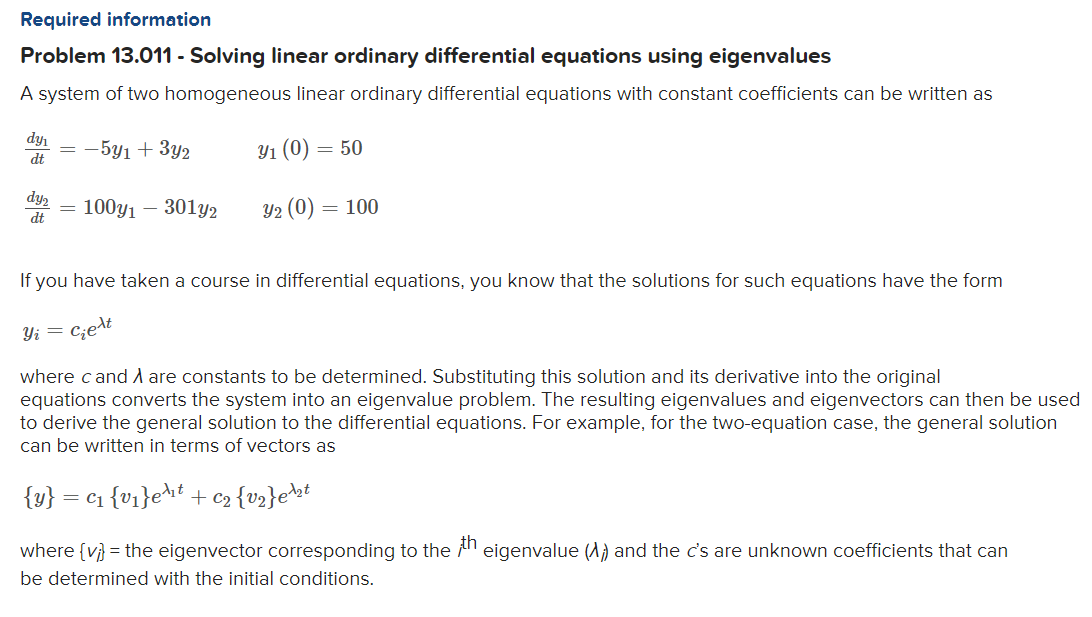

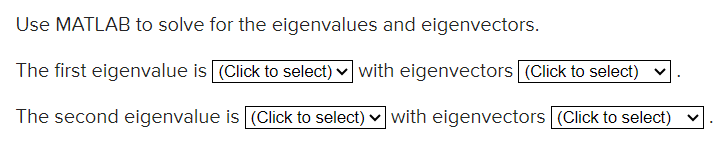

Original ODE

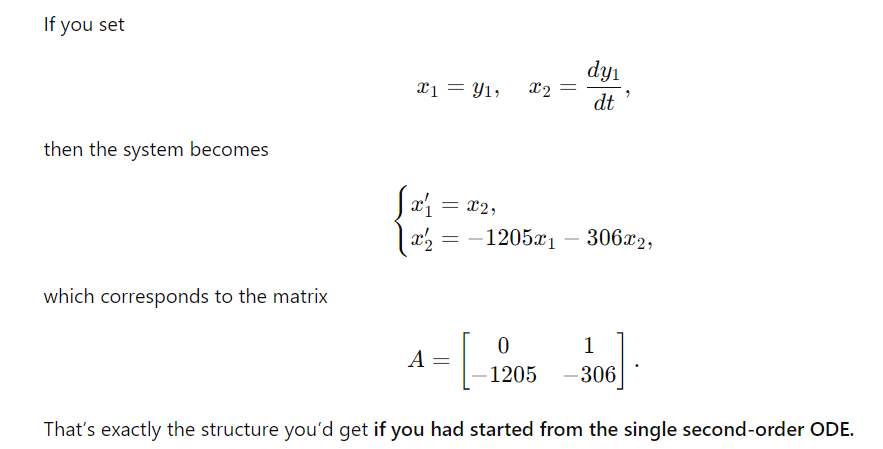

help eig

 eig    Eigenvalues and eigenvectors.
    E = eig(A) produces a column vector E containing the eigenvalues of 
    a square matrix A.
 
    [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    a full matrix V whose columns are the corresponding eigenvectors  
    so that A*V = V*D.
  
    [V,D,W] = eig(A) also produces a full matrix W whose columns are the
    corresponding left eigenvectors so that W'*A = D*W'.
 
    [...] = eig(A,"nobalance") performs the computation with balancing
    disabled, which sometimes gives more accurate results for certain
    problems with unusual scaling. If A is symmetric, eig(A,"nobalance")
    is ignored since A is already balanced.
 
    [...] = eig(A,"balance") is the same as eig(A).
 
    E = eig(A,B) produces a column vector E containing the generalized 
    eigenvalues of square ma

% Goal: get y' = Ay

% x1 = y1;
% x2 = y1' = x1'

% x1' = x2
% x2' = y'' = -1205x1 -306x2

% Or already in the right form
% y1' = -5y1 + 3y2
% y2' = 100y1 - 301y2

A = [-5 3; 100 -301];
b = [50; 100];
[V, D] = eig(A)

V =     0.9477   -0.0101
    0.3191    0.9999


D =    -3.9899         0
         0 -302.0101


Solution

clear,clc,clf,format long
A=[-5 3;100 -301];
p=poly(A)

p =                          1                       306                      1205


d=roots(p)

d =          -302.010066774027
         -3.98993322597295


So MATLAB pairs:

- eigenvalue `λ₁ = -3.9899332259` with eigenvector `v₁ = V(:,1) = [0.9477249; 0.3190885]`.

- eigenvalue `λ₂ = -302.0100667740` with eigenvector `v₂ = V(:,2) = [-0.01010015; 0.99994899]`.